test = readtable("matlab_1_test.csv");
train = readtable("matlab_1_train.csv");

x_train = train(:, {'yield_of_CT', 'Tmax', 'Tmin'});
y_train = train(:, {'Relative_yield_change'});

x_test = test(:, {'yield_of_CT', 'Tmax', 'Tmin'});
y_test = test(:, {'Relative_yield_change'});
x_array = table2array(x_train);
y_array = table2array(y_train);

genOpt = genfisOptions('GridPartition');
genOpt.NumMembershipFunctions = 3;
genOpt.InputMembershipFunctionType = 'trapmf';
inFIS = genfis(x_array, y_array, genOpt);

opt = anfisOptions;
opt.InitialFIS = inFIS;
opt.EpochNumber = 10;
opt.DisplayANFISInformation = 1;
opt.DisplayErrorValues = 1;
opt.DisplayStepSize = 1;
opt.DisplayFinalResults = 1;

test_fis = anfis([x_train{:,:}, y_train{:,:}],opt);

ANFIS info:
	Number of nodes: 78
	Number of linear parameters: 108
	Number of nonlinear parameters: 36
	Total number of parameters: 144
	Number of training data pairs: 989
	Number of checking data pairs: 0
	Number of fuzzy rules: 27


Start training ANFIS ...

1 	 0.192648
2 	 0.192644
3 	 0.192518
4 	 0.192461
5 	 0.192494
6 	 0.192266
7 	 0.192347
Step size decreases to 0.009000 after epoch 8.
8 	 0.19219
9 	 0.192346
10 	 0.192101

Designated epoch number reached. ANFIS training completed at epoch 10.

Minimal training RMSE = 0.192101


x_test = table2array(x_test);
y_test = table2array(y_test);


Plot Membership Functions

y_predicted = evalfis(test_fis, x_test);

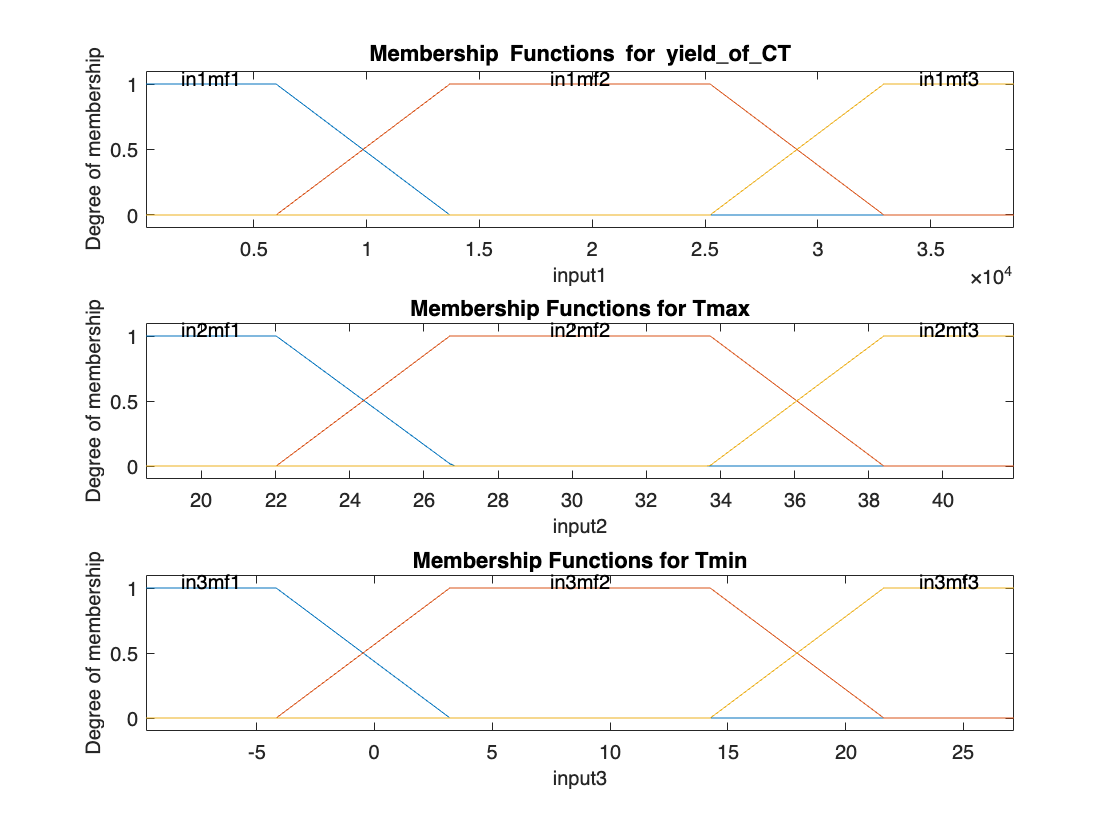


subplot(3, 1, 1);
plotmf(test_fis, 'input', 1);
title('Membership Functions for yield\_of\_CT');

subplot(3, 1, 2);
plotmf(test_fis, 'input', 2);
title('Membership Functions for Tmax');

subplot(3, 1, 3);
plotmf(test_fis, 'input', 3);
title('Membership Functions for Tmin');